## ** Evaluate the double integrals**

(i) $\int_{1}^{3} \int_{0}^{1} {\left(1+4\mathrm{x}\mathrm{y}\right)}\mathrm{d}\mathrm{x}\mathrm{d}\mathrm{y}$

syms x y
f=1+4*x*y

$$f = 4\,x\,y+1$$

int(int(f,x,0,1),y,1,3)

$$ans = 10$$

(ii) $\int_{0}^{1} \int_{\mathrm{x}}^{2-\mathrm{x}} {\left({\mathrm{x}}^2 -\mathrm{y}\right)}\mathrm{d}\mathrm{x}\mathrm{d}\mathrm{y}$ 

f=x^2-y

$$f = x^{2}-y$$

int(int(f,y,x,2-x),x,0,1)

$$ans = -\frac{5}{6}$$

(iii) $\int_{0}^{\pi /2} \int_{0}^{\cos \theta } {\mathrm{e}}^{\sin \theta } \mathrm{d}\mathrm{r}\mathrm{d}\theta$

syms r theta
f=exp(sin (theta))

$$f = {\mathrm{e}}^{\sin\left(\theta \right)}$$

int(int(f,r,0,cos(theta)),theta,0,pi/2)

$$ans = \mathrm{e}-1$$

(iv) $\int_{0}^{2} \int_{0}^{\pi } \mathrm{r}\mathrm{s}\mathrm{i}\mathrm{n}\theta \mathrm{d}\mathrm{r}\mathrm{d}\theta$

syms r theta
f=r* sin (theta)

$$f = r\,\sin\left(\theta \right)$$

int(int(f,theta,0,pi),r,0,2)

$$ans = 4$$

(v)$\underset{\mathrm{R}}{\text{∬}} \frac{\mathrm{x}{\mathrm{y}}^2 }{{\mathrm{x}}^2 +1}\mathrm{d}\mathrm{A}$  $\left.\mathrm{R}={\left\{{\left(\mathrm{x},\mathrm{y}\right)}\right|}0\le \mathrm{x}\le 1,\mathrm{ }\mathrm{ }\mathrm{ }-3\le \mathrm{y}\le 3\right\rbrace$

f=(x*y^2)/(x^2+1)

$$f = \frac{x\,y^{2}}{x^{2}+1}$$

int(int(f,x,0,1),y,-3,3)

$$ans = \log\left(512\right)$$

## Jacobian

syms r theta
a=jacobian([r*cos(theta),r*sin(theta)],[r,theta])

$$a = \left(\begin{array}{cc} \cos\left(\theta \right) & -r\,\sin\left(\theta \right)\\ \sin\left(\theta \right) & r\,\cos\left(\theta \right) \end{array}\right)$$

simplify(det(a))

$$ans = r$$

##  **Evaluate by converting to polar**

(i)$\int_{0}^{1} \int_{0}^{\sqrt{1-{\mathrm{x}}^2 }} {\mathrm{e}}^{{\mathrm{x}}^2 +{\mathrm{y}}^2 } \mathrm{d}\mathrm{y}\mathrm{d}\mathrm{x}=\int_{\theta =0}^{\frac{\pi }{2}} \int_{r=0}^1 e^{\left(r^2 \right)} \mathrm{rdrd}\theta$

syms x y r theta
f=exp(x^2+y^2)

$$f = {\mathrm{e}}^{x^{2}+y^{2}}$$

fpolar=simplify(subs(f,[x,y],[r*cos(theta),r*sin(theta)]))

$$fpolar = {\mathrm{e}}^{r^{2}}$$

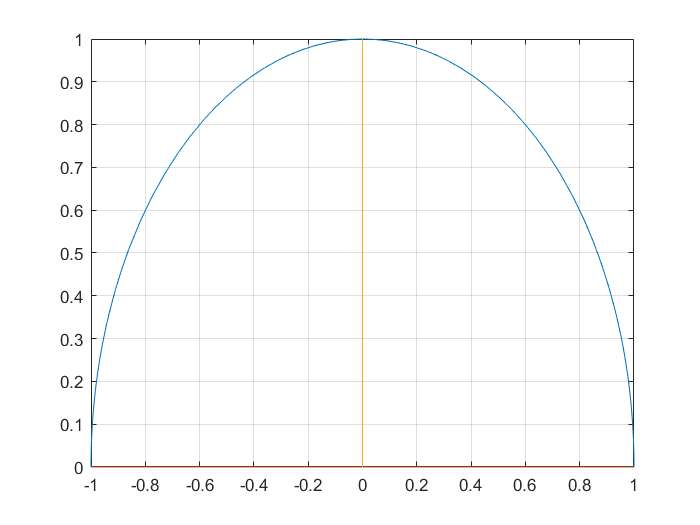

%for plotting the region
fplot(sqrt(1-x^2))
hold on
plot([-1 1],[0 0])
plot([0 0],[0 1])
hold off
grid on

integrand=r*fpolar

$$integrand = r\,{\mathrm{e}}^{r^{2}}$$

int(int(integrand,r,0,1),theta,0,pi/2)

$$ans = \frac{\pi \,\left(\mathrm{e}-1\right)}{4}$$

(ii)$\int_{0}^{2} \int_{0}^{\sqrt{2\mathrm{x}-{\mathrm{x}}^2 }} \sqrt{{\mathrm{x}}^2 +{\mathrm{y}}^2 }\mathrm{d}\mathrm{y}\mathrm{d}\mathrm{x}=\int_{\theta =0}^{\frac{\pi }{2}} \int_{r=0}^{2\mathrm{cos}\theta } r^{2\text{\,}} \mathrm{drd}\theta$

syms x y r theta
f=sqrt(x^2+y^2)

$$f = \sqrt{x^{2}+y^{2}}$$

fpolar=simplify(subs(f,[x y],[r*cos(theta),r*sin(theta)]))

$$fpolar = \sqrt{r^{2}}$$

integrand=r*fpolar

$$integrand = r\,\sqrt{r^{2}}$$

int(int(integrand,r,0,2*cos(theta)),theta,0,pi/2)

$$ans = \frac{16}{9}$$

## **Use double integral to find area of the region**

**(i) area bounded by the parabola **$\mathrm{y}={\mathrm{x}}^2$** and the line**$\text{\,}\mathrm{y}=2\mathrm{x}+3$**  .            **          

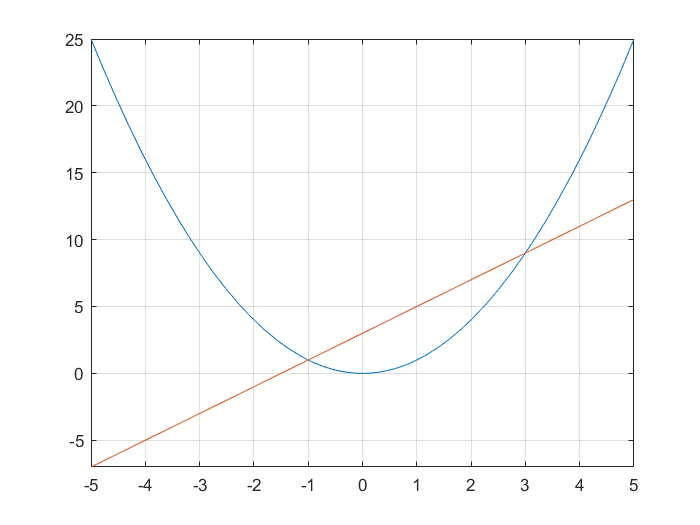

syms x y
par=x^2;
line=2*x+3;
fplot(par)
hold on 
fplot(line)
grid on
hold off

xvalues=solve(par==line)

$$xvalues = \left(\begin{array}{c} -1\\ 3 \end{array}\right)$$


%points of intersection are (-1,1) and (3,9)
int(int(1,y,x^2,2*x+3),x,-1,3)

$$ans = \frac{32}{3}$$

**(ii) smaller of the areas bounded by the circle**$\text{\,}{\mathrm{x}}^2 +{\mathrm{y}}^2 =9$**  and line **$\mathrm{x}+\mathrm{y}=3$

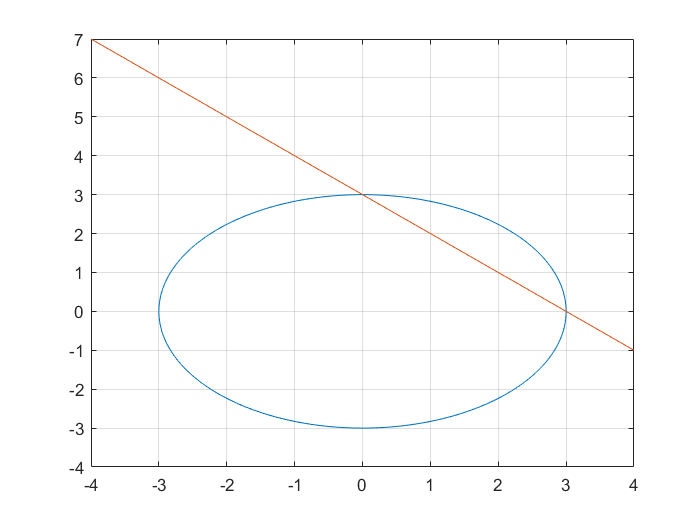

syms x y
fimplicit(x^2+y^2-9,[-4 4])
hold on
fplot(3-x,[-4 4])
grid on
hold off

int(int(1,y,3-x,sqrt(9-x^2)),x,0,3)

$$ans = \frac{9\,\pi }{4}-\frac{9}{2}$$

**(iii)The region inside the circle **$\text{\,}\mathrm{r}=4\sin \theta$**  and outside the circle **$r=2$

clear
syms r theta
r1=4*sin(theta);
r2=2;
%to find the point of intersection
thetavalues=solve(r1==r2)

$$thetavalues = \left(\begin{array}{c} \frac{\pi }{6}\\ \frac{5\,\pi }{6} \end{array}\right)$$

int(int(r,r,2,4*sin(theta)),theta,pi/6,5*(pi/6))

$$ans = \frac{4\,\pi }{3}+2\,\sqrt{3}$$

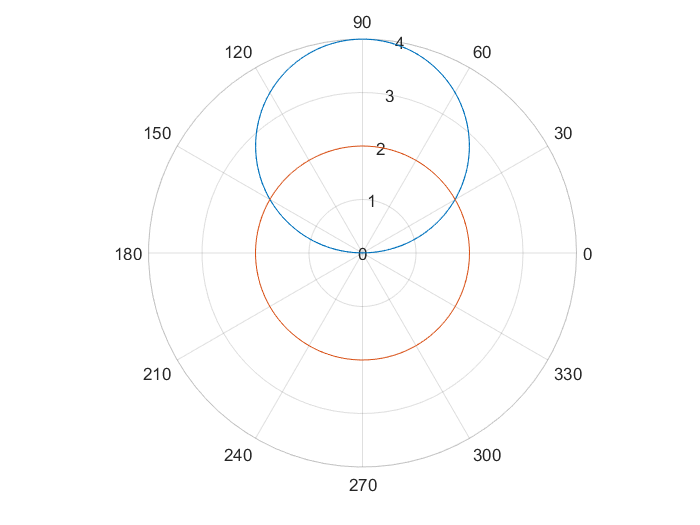

% to plot the two circles
theta = linspace(0,2*pi);
r1 = 4*sin(theta);
polarplot(theta,r1)
hold on
r2=2*ones(1,100);
polarplot(theta,r2)

**Q. An agricultral sprinkler distributes water in a circular pattern of radius 100ft. It supplies water to a depth of **$e^{-r}$** feet per hour at adistance of r feet from the sprinkler.**

**(a) If  **$0<r<100$**, what is the total amount of water supplied per hour to the region between the circle of radius r=5 and r=100, centered at the sprinkler?**

**(b) determine the average amount of water per hour per square foot supplied to the region inside the circle of radius 5 and 100 feet.**

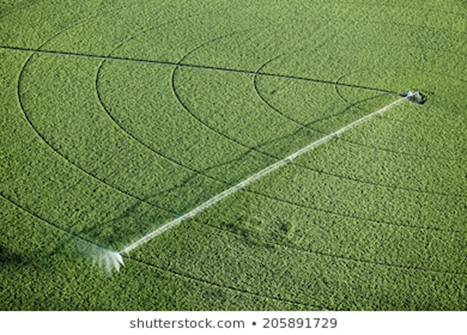

syms r theta
I=r*exp(-r)

$$I = r\,{\mathrm{e}}^{-r}$$

%volume of water supplied to the region within 5 feet of the sprinkler
V1=double(int(int(I,r,0,5),theta,0,2*pi))

V1 = 6.0292

%volume of water supplied to the region within 100 feet of the sprinkler
V2=double(int(int(I,r,0,100),theta,0,2*pi))

V2 = 6.2832

% area of the region
A1=pi*25

A1 = 78.5398

%The average amount of water per hour per square foot supplied to the rgion within 5 feet 
Avgwater1=V1/A1

Avgwater1 = 0.0768


A2=pi*10000

A2 = 3.1416e+04

%The average amount of water per hour per square foot supplied to the rgion within 5 feet 
Avgwater1=V2/A2

Avgwater1 = 2.0000e-04

**Q. The population density of fireflies in a field is given by **$f=\frac{1}{100}x^2 y$** where **$0\le x\le 30$** and **$0\le y\le 20$**, x and y are in feet, and f is the number of fireflies fer square foot. Determine the total population of fireflies in the field.**

**Solution: As **$\mathrm{Total}\;\mathrm{mass}\;\left(m\right)=\int \int \rho \left(x,y\right)\mathrm{dA}$ where $\rho \left(x,y\right)$is the density.

syms x y
f=(1/100)*x^2*y

$$f = \frac{x^{2}\,y}{100}$$

P=int(int(f,x,0,30),y,0,20)

$$P = 18000$$

**Q. The density of students living near a university is modeled by **$\;p\left(x,y\right)=9-x^2 -y^2 \;$**. where x and y are in miles and p is the number of students per square mile, in hundreds. Assume the university is located at (0,0). Find the number of students who live in the shaded region shown below.**

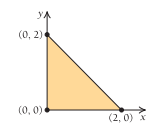

p=9-x^2-y^2

$$p = -x^{2}-y^{2}+9$$

Population=double(int(int(p,x,0,2),y,0,2))

Population = 25.3333